# Práctica 1: Aerobalancín

Amelia Hoyos Vélez y Esteban Álvarez Zuluaga

### 1. Introducción 

#### 1.1 Planteamiento del problema

El aerobalancín, balancín eólico o aeropéndulo doble es un dispositivo empleado en laboratorios de control para la validación experimental de estrategias de control que posteriormente se aplican en sistemas de la industria aeroespacial y mecatrónica, como por ejemplo en vehículos autónomos no tripulados [1]. Este modelo permite estudiar una plataforma considerablemente más simple que las utilizadas en aplicaciones industriales reales, ya que posee un único grado de libertad. No obstante, conserva una estructura MISO (Multiple Input Single Output) que proporciona una dinámica suficientemente rica para el análisis y diseño de estrategias de control. Por esta razón, el estudio de este sistema constituye un ejercicio cuyos resultados pueden extrapolarse a problemas del mundo real.

En el caso del aerobalancín, el problema se formula como el modelado matemático de un péndulo cuyo pivote no se encuentra en uno de sus extremos, sino en una posición intermedia de la barra, lo que implica que uno de sus lados pueda ser más largo que el otro. En ambos extremos de la barra se disponen hélices propulsoras, controladas de manera independiente, que generan dos pares de control aplicados al sistema.

El objetivo principal es obtener una descripción analítica de la dinámica no lineal del sistema y llevar a cabo simulaciones numéricas que permitan analizar su comportamiento. A partir de este análisis, se pretende diseñar estrategias de control óptimo orientadas, por ejemplo, a la estabilización del sistema en torno a un punto de equilibrio arbitrario.

#### 1.2 Modelo matemático.

El modelo se deriva de sistemas similares, como el aeropéndulo con una sola hélice propulsora [2], [3]. El sistema del aerobalancín consiste en una barra rígida sujeta a un pivote en cuyos extremos están acoplados dos motores con hélices. Cada hélice genera una fuerza de empuje perpendicular a la barra, la cual induce un momento de fuerza que hace girar el sistema alrededor de su pivote, ubiccado en el origen del sistema de referencia. 

Supongamos que la fuerza de empuje $T_1$ que produce el primer motor a una distancia $l_1$ del pivote genera un momento positivo $\vec{M}_1 = l_1 \times T_1$ y que $T_2$ producida por el segundo motor a una distancia $l_2$ del pivote genera un momento negativo $\vec{M}_2 = l_2 \times T_2$. El centro de gravedad del sistema puede no coincidir con el pivote, por lo que el peso del aeropéndulo también produce un momento de fuerza. Dicho momento viene dado por $\vec{M_3} = mgd\sin(\phi)  $, donde $g$ es la aceleración debida a la gravedad, $m$ es la masa del péndulo, $d$ es la distancia desde el pivote hasta el centro de gravedad, y $\phi$ es el ángulo positivo medido entre el eje$y$ negativo y el eje$1$del péndulo. La masa del sistema es $m = m_b + m_1+m_2$, donde $m_b$ es la masa de la barra, $m_1$es la masa del primer motor y $m_2$ la masa del segundo motor.

Por último, la fuerza de arrastre del aire, que se opone al movimiento, se modela mediante un término lineal de rozamiento viscoso $\vec{M_4} = -c\dot{\theta}$ donde $c$ es el coeficiente de amortiguamiento viscoso del aire, $\theta = \frac{\pi}{2} - \phi$ es el ángulo medido respecto a la horizontal positiva y $\dot{\theta}$ es su velocidad angular.

**Figura 1. Diagrama de cuerpo libre de un aerobalancín**

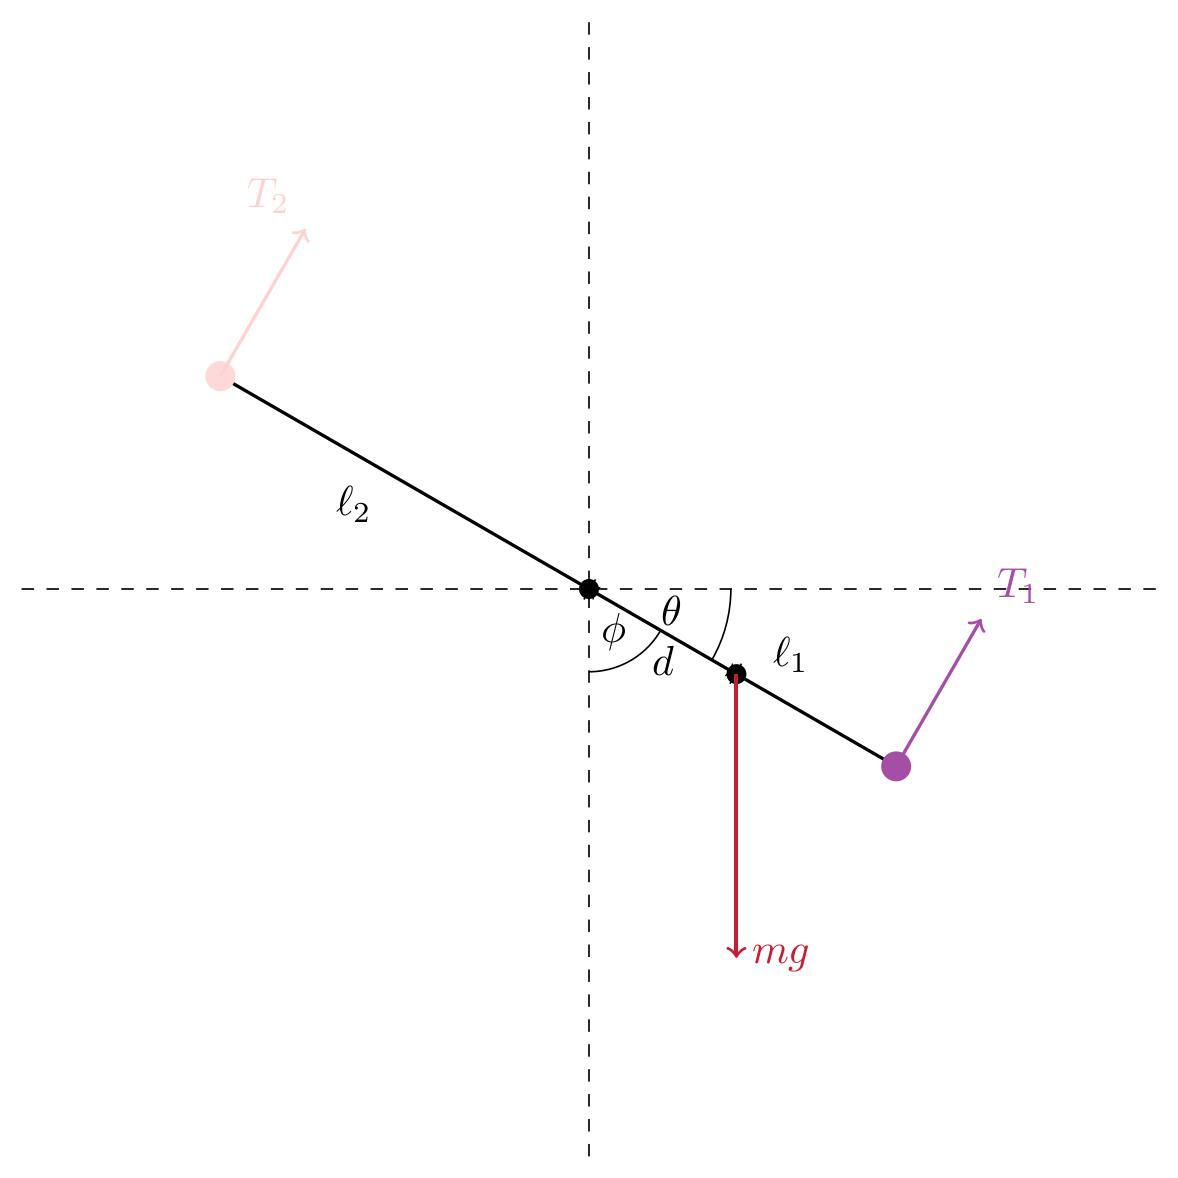

Según la formulación de Newton–Euler que describe la dinámica de sólidos rígidos, suponiendo un movimiento rotacional alrededor de un eje fijo de un cuerpo rígido con un momento de inercia constante y momentos respecto a dicho eje [4], la dinámica del sistema puede expresarse mediante

$J\ddot{\theta} = \sum_{i=1}^4 \vec{M_i} $,

donde $J$ es el momento de inercia rotacional del sistema. La ecuación dinámica del sistema es,

$J\ddot{\theta} = T_1l_1 - T_2l_2 - mgd\sin(\phi) - c\dot{\theta}$.

La ecuación, debido a que $\theta = \frac{\pi}{2} - \phi$, se reescribe como

$J\ddot{\theta} = T_1l_1 - T_2l_2 - mgd\cos\left( \theta\right) - c\dot{\theta}$.

En base al modelo teórico, se construye el sistema de variables de estado. Se asigna,


$$x_1 = \theta, \qquad x_2 = \dot{\theta}, \qquad u_1 = T_1, \qquad u_2 = T_2.

$$


Así que,


$$\mathbf{x} = \left[\begin{array}{c} x_1 \\ x_2 \end{array}\right], \qquad \mathbf{u} = \left[\begin{array}{c} u_1 \\ u_2 \end{array}\right].$$


El sistema de variables de estado es,


$$\left\{\begin{array}{l} \dot{x}_1 = x_2, \\ \dot{x}_2 = \frac{1}{J}\left(u_1 l_1 - u_2 l_2 - mgd\cos x_1 - cx_2\right). \end{array}\right.$$


En forma vectorial,


$$\dot{\mathbf{x}} = \left[\begin{array}{c} x_2 \\ \frac{1}{J}\left(u_1 l_1 - u_2 l_2 - mgd\cos x_1 - cx_2\right) \end{array}\right].$$


Así que $\dot{x} = f(\mathbf{x},\mathbf{u})$. Como puede verse, el modelo es no lineal debido al término $\frac{mgd}{J}\cos x_1$ que es de segundo orden.

#### 1.3 Variables y Parámetros del Modelo

El modelo del balancín eólico se formula a partir de los parámetros, variables de estado y entradas del sistema, los cuales se presentan en las Tablas 1, 2 y 3, respectivamente.

**Tabla 1: Parámetros del modelo**

**Tabla 2: Variables de estado del modelo**

**Tabla 3: Entradas del modelo**

#### 1.4 Hipótesis

### 2. Métodos

### 3. Resultados

### **3.1 Variables por defecto y funciones auxiliares**

Se impondrán los siguentes parámetros físicos por defecto, 

$
m_b = 0.1 \ \text{kg}, \qquad
m_1 = 0.2 \ \text{kg}, \qquad
m_2 = 0.2 \ \text{kg}, \qquad
m = 0.5 \ \text{kg}, \qquad
l_1 = 0.4 \ \text{m},\qquad
l_2 = 0.2 \ \text{m}, \qquad 
d = 0.2 \ \text{m}, \qquad
g = 9.81 \ \text{m/s}^2, \qquad
c = 0.1, \ \text{N\cdot m\cdot s/rad}
$.

Si el punto $d$está sobre $l_1$, se define como positivo, y si está sobre $l_2$ es negativo. El momento de inercia del aerobalancín respecto al pivote se obtiene considerando la contribución de cada uno de los elementos del sistema: la barra y los motores ubicados en sus extremos. Para trasladar los momentos de inercia al eje de rotación del sistema se emplea el teorema de ejes paralelos.

$J = J_{\text{barra}} + J_{\text{motor}_1} + J_{\text{motor}_2} = 
\left(\frac{1}{12} m_b L^2 + m_b d^2 \right)
+ m_1 l_1^2
+ m_2 l_2^2$.

Las condiciones iniciales del sistema se impondrán como $\theta(0) = 0 \ \text{rad}, \dot{\theta}(0) = 0 \ \text{rad/s}$. Las entradas del sistema son $T_1 = T_2 = 1 \text{ N}$.

clear; clc; close all;
figura = 2
tabla = 4

% Parámetros físicos
params.mb = 0.1;       % Masa de la barra (kg)
params.m1 = 0.2;       % Masa del rotor 1 (kg)
params.m2 = 0.2;       % Masa del rotor 2(kg)
params.l1 = 0.4;       % Distancia al rotor 1 (m)
params.l2 = 0.2;       % Distancia al rotor 2 (m)
params.g = 9.81;       % Gravedad (m/s^2)
params.c = 0.1;        % Coeficiente de amortiguamiento (N·m·s/rad)

%% Condiciones iniciales
theta0 = 0;            % Posición en rad
theta_dot0 = 0;        % Velocidad angular en rad/s

x0 = [theta0; theta_dot0];

function params = aeropendulum_compute_params(params)

    % Longitud total de la barra
    params.L = params.l1 + params.l2;
    
    % Distancia del pivote al centro de gravedad
    params.d = (params.l1 + params.l2)/2 - params.l2;
    
    % Masa total
    params.m = params.mb + params.m1 + params.m2;
    
    % Momento de inercia de la barra
    J_bar = (1/12)*params.mb*params.L^2 + params.mb*params.d^2;
    
    % Momento de inercia de los rotores
    J_r1 = params.m1 * params.l1^2;
    J_r2 = params.m2 * params.l2^2;
    
    % Momento de inercia total
    params.J = J_bar + J_r1 + J_r2;

end

params = aeropendulum_compute_params(params);

Se presenta la dinámica del modelo codificada, con una función auxiliar que permite definir la entrada que se aplicará al sistema.

% Ecuación dinámica del aerobalancín
function dx = aeropendulum_dynamics(t,x,params,thrust_fun)
    
    % Entradas:
    %   t           -> tiempo
    %   x           -> vector de estado [theta; theta_dot]
    %   params      -> parámetros físicos del sistema
    %   thrust_fun  -> función de empuje [T1,T2] = thrust_fun(t,theta,theta_dot)
    %
    % Salida:
    %   dx          -> derivada del vector de estado
    
    %% Estados
    theta = x(1);
    theta_dot = x(2);
    
    % Mantener theta en [-pi, pi]
    theta = atan2(sin(theta),cos(theta));
    
    %% Empujes de los rotores
    [T1,T2] = thrust_fun(t,theta,theta_dot);
    
    %% Dinámica del sistema
    theta_ddot = ( ...
          T1*params.l1 ...
        - T2*params.l2 ...
        - params.m*params.g*params.d*sin(pi/2 - theta) ...
        - params.c*theta_dot ...
        ) / params.J;
    
    %% Vector de derivadas
    dx = [theta_dot; theta_ddot];

end
% Modelo de empuje constante para los rotores del aerobalancín.
function [T1,T2] = thrust_constant(~, ~, ~)
% Salidas:
%   T1 -> Empuje generado por el rotor 1 (N)
%   T2 -> Empuje generado por el rotor 2 (N)

    T1 = 1;   % Empuje constante del rotor 1 (N)
    T2 = 1;   % Empuje constante del rotor 2 (N)
end

Se definen algunas funciones auxiliares para resolver el problema. Entre estas se encuentra una función para simular el comportamiento del aeropéndulo mediante el método de Runge–Kutta.

% Simula la dinámica del aerobalancín
function [t,theta,theta_dot,sol] = simulate_aeropendulum(params,x0,tspan,thrust_fun)

    % Entradas:
    %   params      -> parámetros físicos del sistema
    %   x0          -> condiciones iniciales [theta0; theta_dot0]
    %   tspan       -> vector de tiempo de simulación
    %   thrust_fun  -> función de empuje de los rotores
    %
    % Salidas:
    %   t           -> vector de tiempo
    %   theta       -> posición angular en [-pi,pi]
    %   theta_dot   -> velocidad angular (rad/s)
    %   sol         -> solución completa del sistema

    % Resolver el sistema dinámico (Runge-Kutta 4,5)
    [t,sol] = ode45(@(t,x) aeropendulum_dynamics(t,x,params,thrust_fun), tspan, x0);

    % Variables de estado
    theta = mod(sol(:,1) + pi, 2*pi) - pi;   % mantener en [-pi,pi]
    theta_dot = sol(:,2);

end

La siguiente función grafica los estados del aerobalancín en función del tiempo.

function plot_aeropendulum_states(t,theta,theta_dot)
% Entradas:
%   t         -> vector de tiempo (s)
%   theta     -> posición angular (rad)
%   theta_dot -> velocidad angular (rad/s)

    figure
    plot(t,theta,'b','LineWidth',1.5)
    hold on
    plot(t,theta_dot,'r','LineWidth',1.5)
    
    xlabel('Tiempo (s)')
    ylabel('Estados')
    legend('Posición (rad)','Velocidad angular (rad/s)')
    grid on
end

La siguiente función es para animar los resultados de la simulación bajo los parámetros seleccionados.

function animate_aeropendulum(t, theta, theta_dot, parameters, thrust_fun)
% Entradas:
% t         -> Vector de tiempo obtenido de la simulación (s)
% theta     -> Vector del ángulo del aeropéndulo en cada instante (rad)
% theta_dot -> Vector de la velocidad angular (rad/s)
% params    -> Estructura con parámetros físicos del sistema
% thrust_fun-> Función de empuje de los rotores [T1,T2] = thrust_fun(t,theta,theta_dot)

% Extraer parámetros geométricos
l1 = parameters.l1;
l2 = parameters.l2;
d  = parameters.d;

theta = mod(theta + pi, 2*pi) - pi;

%% Crear figura con margen suficiente para etiquetas
fig = figure('Position', [100 100 1300 550]);

%% -------- Pendulum animation (ax1) --------
ax1 = subplot(1,2,1);
axis(ax1, 'equal');
axis(ax1, [-0.6 0.6 -0.6 0.6]);
grid(ax1, 'on');
box(ax1, 'on');

% Axis labels
xlabel(ax1, 'X (m)', 'Interpreter', 'tex', 'FontSize', 13);
ylabel(ax1, 'Y (m)', 'Interpreter', 'tex', 'FontSize', 13);
title(ax1,  'Aeropéndulo con Doble Rotor', ...
    'Interpreter', 'tex', 'FontSize', 13, 'FontWeight', 'bold');

hold(ax1, 'on');

% Graphical elements
pivot = plot(ax1, 0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
bar   = plot(ax1, [0 0], [0 0], 'b-', 'LineWidth', 3);
r1    = plot(ax1, 0, 0, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'm');
r2    = plot(ax1, 0, 0, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
cg    = plot(ax1, 0, 0, 'mx', 'MarkerSize', 10, 'LineWidth', 2);

% T1/T2 labels placed INSIDE axes using data coordinates (top-left corner)
% Avoids clipping that occurs with normalized units near figure edge
label_T1 = text(ax1, -0.57, 0.57, '$T_1 = 0.00\ \mathrm{N}$', ...
    'Interpreter', 'latex', 'FontSize', 11, ...
    'HorizontalAlignment', 'left', ...
    'VerticalAlignment',   'top',  ...
    'Color', 'm', ...
    'BackgroundColor', 'white', 'EdgeColor', 'none');

label_T2 = text(ax1, -0.57, 0.46, '$T_2 = 0.00\ \mathrm{N}$', ...
    'Interpreter', 'latex', 'FontSize', 11, ...
    'HorizontalAlignment', 'left', ...
    'VerticalAlignment',   'top',  ...
    'Color', [0.1 0.6 0.1], ...
    'BackgroundColor', 'white', 'EdgeColor', 'none');

%% -------- Angle plot (ax2) --------
ax2 = subplot(1,2,2);
grid(ax2, 'on');
box(ax2, 'on');

xlabel(ax2, 'Tiempo (s)',   'Interpreter', 'tex', 'FontSize', 13);
ylabel(ax2, '\theta (rad)', 'Interpreter', 'tex', 'FontSize', 13);
title(ax2,  'Evolución del Ángulo', ...
    'Interpreter', 'tex', 'FontSize', 13, 'FontWeight', 'bold');

hold(ax2, 'on');

angle_line    = animatedline(ax2, 'Color', 'b', 'LineWidth', 2);
current_point = plot(ax2, t(1), theta(1), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'none');

ylim(ax2, [-pi pi]);
xlim(ax2, [t(1) t(end)]);

% Pi-fraction y-ticks
set(ax2,'YTick',[-pi -pi/2 0 pi/2 pi])
set(ax2,'YTickLabel', {'-\pi','-\pi/2','0','\pi/2','\pi'})
set(ax2, 'TickLabelInterpreter', 'tex');

%% Manually set subplot positions to prevent ylabel clipping
set(ax1, 'Position', [0.08  0.12  0.37  0.76]);
set(ax2, 'Position', [0.58  0.12  0.37  0.76]);

%% -------- Animation loop --------
for k = 1:length(t)
    th    = theta(k);
    thdot = theta_dot(k);

    x1  =  l1 * cos(th);   y1  =  l1 * sin(th);
    x2  = -l2 * cos(th);   y2  = -l2 * sin(th);
    xcg =   d * cos(th);   ycg =   d * sin(th);

    set(bar, 'XData', [x2 x1], 'YData', [y2 y1]);
    set(r1,  'XData', x1, 'YData', y1);
    set(r2,  'XData', x2, 'YData', y2);
    set(cg,  'XData', xcg, 'YData', ycg);

    delete(findall(ax1, 'Type', 'quiver'));

    [T1, T2] = thrust_fun(t(k), th, thdot);
    set(label_T1, 'String', sprintf('$T_1 = %.2f\\ \\mathrm{N}$', T1));
    set(label_T2, 'String', sprintf('$T_2 = %.2f\\ \\mathrm{N}$', T2));

    perp  = th + pi/2;
    scale = 0.05;
    quiver(ax1, x1, y1, scale*T1*cos(perp), scale*T1*sin(perp), 0, ...
        'r', 'LineWidth', 1.5, 'MaxHeadSize', 0.5);
    quiver(ax1, x2, y2, scale*T2*cos(perp), scale*T2*sin(perp), 0, ...
        'Color', [0.1 0.6 0.1], 'LineWidth', 1.5, 'MaxHeadSize', 0.5);

    addpoints(angle_line, t(k), th);
    set(current_point, 'XData', t(k), 'YData', th);

    drawnow limitrate
    pause(0.02);
end
end

#### 3.1.1 Simulación ejemplar

Tomaremos los parámetros previamente seleccionados para una simulación inicial. Simularemos durante 10 segundos, discretizado en 500 puntos.

Cálculo númerico de la simulación.

tspan = linspace(0,10,500);

% Simulación
[t,theta,theta_dot] = simulate_aeropendulum(params,x0,tspan,@thrust_constant);

% Gráfica
plot_aeropendulum_states(t,theta,theta_dot)

Véase que en este caso para $t\gg0$, el sistema se estabiliza, la velocidad $\dot{\theta} \rightarrow 0$ y la posición tiende a una constante.

% Animación
animate_aeropendulum(t,theta,theta_dot,params,@thrust_constant)

### 3.2 Verificación del Modelo

Se procede a verificar el modelo: se probarán distintos escenarios y se compararán con el resultado esperado en la realidad. 

#### **3.2.1 Caso 1: Caso límite de un péndulo simple Ideal**

Se realiza una simulación sin fuerzas de empuje ni rozamiento con un solo brazo de palanca. Se espera que el sistema se comporte como un péndulo simple que no cese de oscilar de manera  sinusoidal.  Se toman los siguientes parámetros y entradas.

%% Parámetros físicos
params1.mb = 0;        % Masa (kg)
params1.m1 = 0.5;        % Masa (kg)
params1.m2 = 0;        % Masa (kg)
params1.l1 = 0.5;       % Distancia al rotor 1 (m)
params1.l2 = 0;       % Distancia al rotor 2 (m)
params1.g = 9.81;       % Gravedad (m/s^2)
params1.c = 0;        % Coeficiente de amortiguamiento (N·m·s/rad)

% Compute d, J, L, m
params1.L = params1.l1 + params1.l2;
params1.m = params1.mb + params1.m1 + params1.m2;
params1.d = params1.l1;
params1.J = params1.m*params1.d^2;

%% Condiciones iniciales para oscilaciones pequeñas
theta01 = 0;            % Posición en rad
theta_dot01 = 0;        % Velocidad angular en rad/s
x01 = [theta01; theta_dot01];


%% ---- Control de empuje nulo ----
function [T1,T2] = thrust_zero(~, ~, ~)
    T1 = 0;
    T2 = 0;
end

Habiendo definido los parámetros se realiza la simulación.

tspan1 = linspace(0,6,500);

% Simulación
[t1,theta1,theta_dot1] = simulate_aeropendulum(params1,x01,tspan1,@thrust_zero);
% Animación
%animate_aeropendulum(t1,theta1,theta_dot1,params1,@thrust_zero)

Nótese que la respuesta para estos parámetros en específico es sinusoidal, por lo que representa un comportamiento límite en concordancia con el del péndulo simple. Se evaluará ahora este comportamiento para distintos valores de $L = l_1$ y se verificará que el periodo de oscilación de la simulación es $T = 2\pi\sqrt{\frac{L}{g}$ como lo predice el modelo de péndulo simple para ángulos $\phi$pequeños. Se probará con $\phi = 10\degree $.

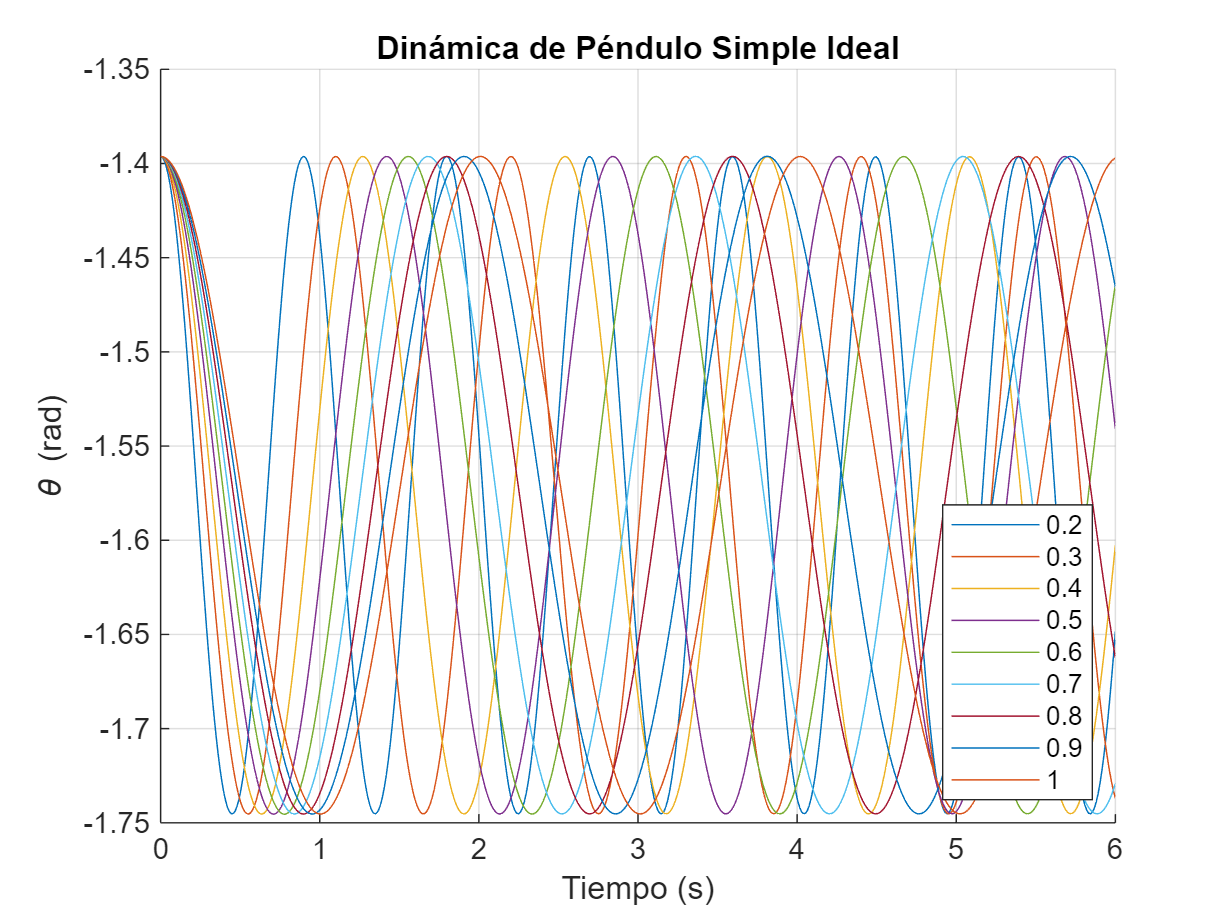

%% Definimos valores de l1 para la simulación de parámetros.
l1_values = linspace(0.2,1,9)';

% Arreglos en los que se guardará el periodo teórico y experimental.
T_sim    = zeros(9,1);   % 9x1 column
T_theory = zeros(9,1);   % 9x1 column

figure
hold on
grid on
xlabel('Tiempo (s)')
ylabel('\theta (rad)')
title('Dinámica de Péndulo Simple Ideal')

%% Condiciones iniciales para oscilaciones pequeñas
theta01 = -1.39626;            % Posición en rad
theta_dot01 = 0;        % Velocidad angular en rad/s
x01 = [theta01; theta_dot01];

for i = 1:9
    params1.l1 = l1_values(i);
    % Recomputar parámetros m, J, L, d
    params1.L = params1.l1 + params1.l2;
    params1.m = params1.mb + params1.m1 + params1.m2;
    params1.d = params1.l1;
    params1.J = params1.m*params1.d^2;

    % Simular sistema
    [t1,theta1,theta_dot1] = simulate_aeropendulum(params1,x01,tspan1,@thrust_zero);
    plot(t1,theta1)

    %% Estimar periodo en base a los picos
    [~,locs] = findpeaks(theta1,t1);

    if length(locs) >= 2
        T_sim(i) = locs(2) - locs(1);
    else
        T_sim(i) = NaN;
    end

    %% Periodo Teórico
    T_theory(i) = 2*pi*sqrt(params1.l1/params1.g);

end
legend(string(l1_values),'Location','southeast')

per_error = abs(T_sim- T_theory)./T_theory * 100;
T_table = table(l1_values, T_sim, T_theory, per_error, ...
    'VariableNames', {'l1_m', 'T_sim_s', 'T_theory_s', 'Error Relativo (%)'});

disp(T_table)

    l1_m    T_sim_s    T_theory_s    Error Relativo (%)
    ____    _______    __________    __________________

    0.2     0.88978     0.89714            0.82047     
    0.3      1.0942      1.0988            0.41679     
    0.4      1.2625      1.2687            0.49048     
    0.5      1.4188      1.4185           0.023569     
    0.6      1.5631      1.5539            0.59423     
    0.7      1.6834      1.6784            0.29617     
    0.8      1.8036      1.7943             0.5198     
    0.9      1.8998      1.9031            0.17457     
      1       2.008      2.0061           0.097173     



Véase que para un ángulo $\phi = 10\degree $ pequeño, el error relativo entre el periodo simulado y el periodo teórico es pequeño. Este error se debe a la linealización para ángulos pequeños $sin(\theta) = \theta$ usada para obtener la relación  $T = 2\pi\sqrt{\frac{L}{g}$ .

#### **3.2.2 Caso 2: Variación de la ubicación del pivote sin fricción viscosa**

Se analiza el efecto de variar la posición del pivote a lo largo de una barra de longitud $L = 30 \text{ cm}$.  Con condiciones iniciales iguales a cero, se analizará el caso primero sin fricción viscosa.

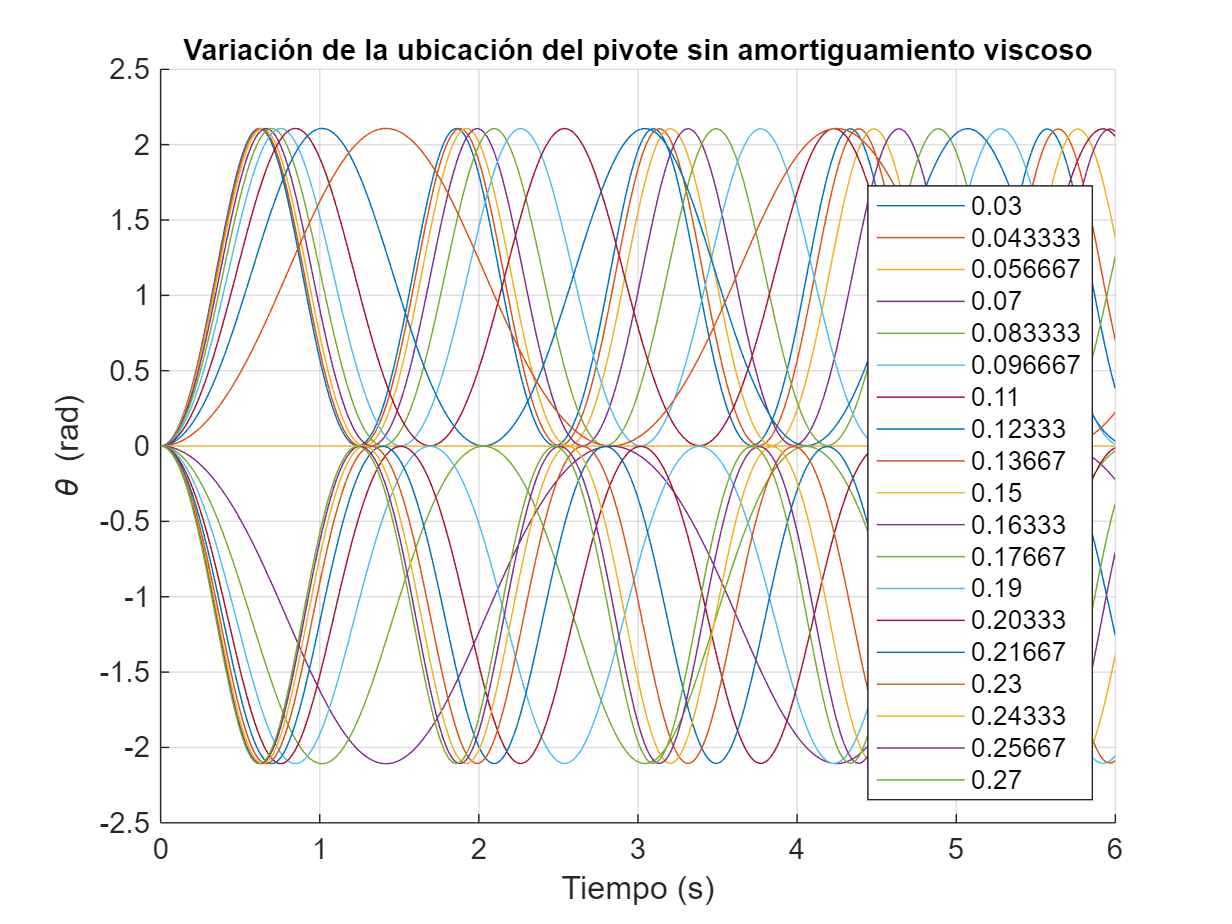

%% Intervalo de tiempo de simulación
tspan2 = linspace(0,6,500);
n = 19; % Número de datos

%% Parámetros físicos del sistema
params2.mb = 0.1;      % Masa del cuerpo central (kg)
params2.m1 = 0.2;      % Masa del rotor 1 (kg)
params2.m2 = 0.2;      % Masa del rotor 2 (kg)
params2.g  = 9.81;     % Aceleración de la gravedad (m/s^2)
params2.c  = 0;        % Coeficiente de amortiguamiento (N·m·s/rad)

%% Condiciones iniciales
theta02 = 0.0;         % Ángulo inicial (rad)
theta_dot02 = 0;       % Velocidad angular inicial (rad/s)
x02 = [theta02; theta_dot02];

%% Valores de l1 que se desean analizar
l1_values = linspace(0.03,0.27,n)';

%% Inicialización de arreglos para almacenar resultados
theta_max = zeros(n,1);   % Valor máximo del ángulo
theta_min = zeros(n,1);   % Valor mínimo del ángulo
d  = zeros(n,1);          % Distancia del pivote al centro de gravedad.
T_sim     = zeros(n,1);   % Periodo estimado de oscilación

%% Figura para visualizar las trayectorias temporales
figure
hold on
grid on
xlabel('Tiempo (s)')
ylabel('\theta (rad)')
title('Variación de la ubicación del pivote sin amortiguamiento viscoso', 'FontSize',10,'FontWeight','bold')

for i = 1:n
    
    %% Actualizar parámetros geométricos
    params2.l1 = l1_values(i);       % Distancia al rotor 1
    params2.l2 = 0.30 - params2.l1;  % Distancia al rotor 2
    
    % Recalcular parámetros derivados del modelo
    params2 = aeropendulum_compute_params(params2);

    %% Simulación del sistema dinámico
    [t2,theta2,theta_dot2] = simulate_aeropendulum(params2,x02,tspan2,@thrust_constant);

    %% Graficar respuesta temporal
    plot(t2,theta2)

    %% Guardar características de la señal
    theta_max(i) = max(theta2);      % Valor máximo
    theta_min(i) = min(theta2);      % Valor mínimo
    d(i)  = params2.d;      % Valor final (equilibrio)

    %% Estimación del periodo usando picos de la señal
    [~,locs] = findpeaks(theta2,t2);

    if length(locs) >= 2
        T_sim(i) = locs(2) - locs(1);   % Diferencia entre dos picos consecutivos
    else
        T_sim(i) = NaN;                 % Si no hay suficientes picos
    end

end

%% Mostrar leyenda con los valores de l1
legend(string(l1_values),'Location','southeast')

%% Crear tabla de resultados
results_table = table(l1_values, theta_max, theta_min, d, T_sim, ...
    'VariableNames', {'l1 (m)','Theta_max (rad)','Theta_min (rad)','d (m)','Periodo (s)'});

disp(results_table)

     l1 (m)     Theta_max (rad)    Theta_min (rad)      d (m)       Periodo (s)
    ________    _______________    _______________    __________    ___________

        0.03        2.1066                     0           -0.12      1.2385   
    0.043333        2.1072                     0        -0.10667      1.2505   
    0.056667         2.107                     0       -0.093333      1.2866   
        0.07        2.1072                     0           -0.08      1.3226   
    0.083333        2.1072                     0       -0.066667      1.3948   
    0.096667        2.1071                     0       -0.053333       1.503   
        0.11        2.1071                     0           -0.04      1.6954   
     0.12333        2.1073                     0       -0.026667      2.0321   
     0.13667        2.1078   

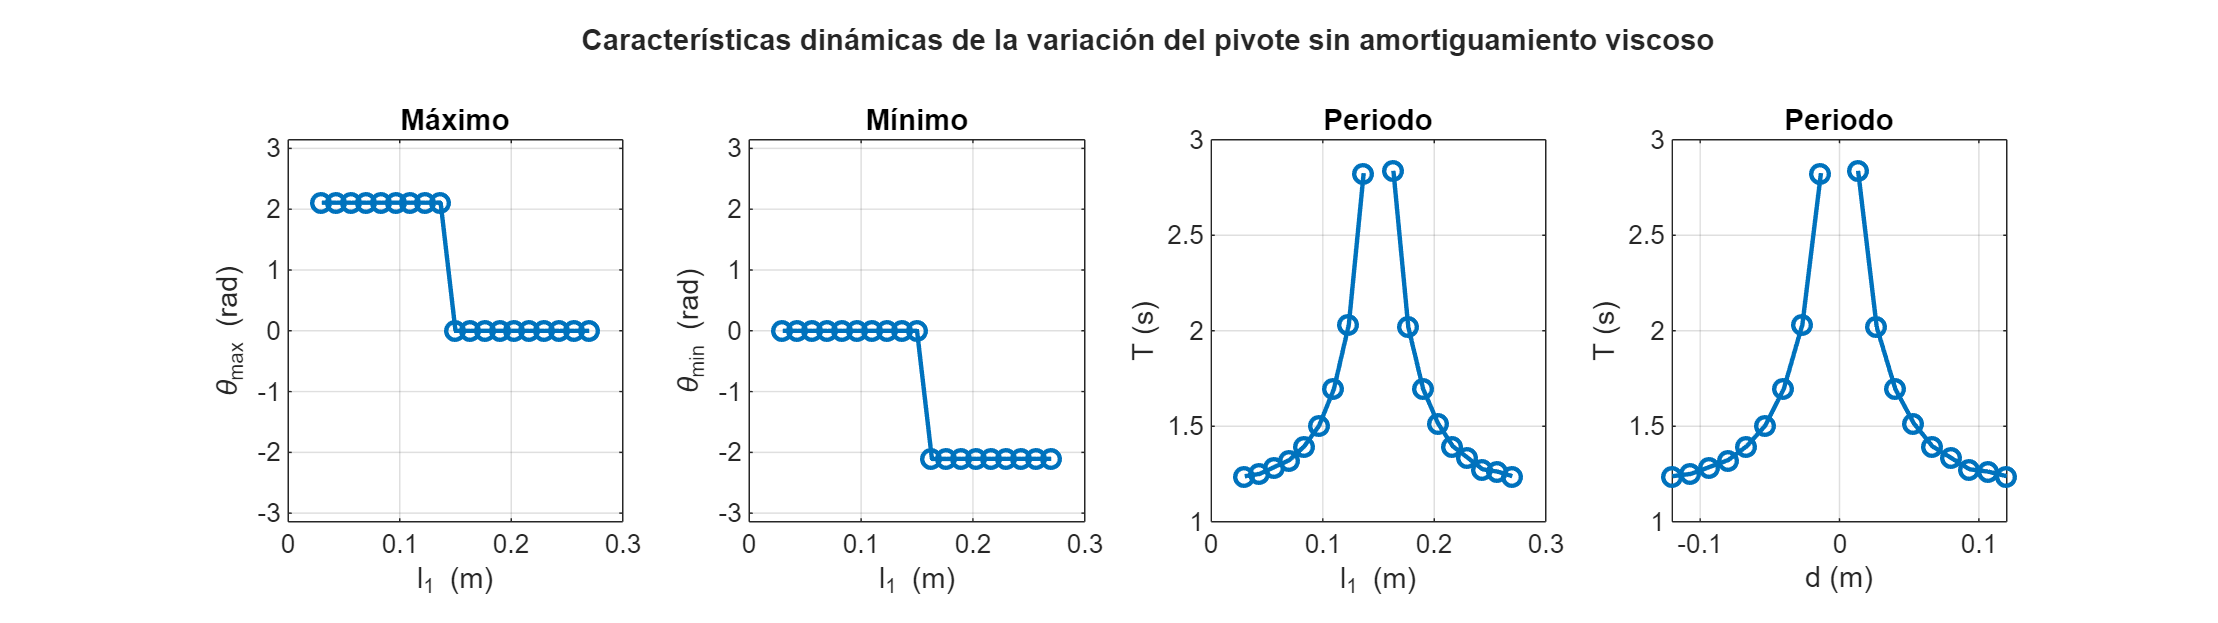

%% Figura resumen de características dinámicas
figure('Units','normalized','Position',[0 0 0.7 0.35])

tiledlayout(1,4)

sgtitle({'Características dinámicas de la variación del pivote sin amortiguamiento viscoso';''}, ...
        'FontSize',10,'FontWeight','bold')

%% Ángulo máximo
nexttile
plot(l1_values,theta_max,'o-','LineWidth',1.5)
xlabel('l_1 (m)')
ylabel('\theta_{max} (rad)')
title('Máximo', 'FontSize',10,'FontWeight','bold')
ylim([-pi pi])
grid on

%% Ángulo mínimo
nexttile
plot(l1_values,theta_min,'o-','LineWidth',1.5)
xlabel('l_1 (m)')
ylabel('\theta_{min} (rad)')
title('Mínimo', 'FontSize',10,'FontWeight','bold')
ylim([-pi pi])
grid on

%% Periodo de oscilación
nexttile
plot(l1_values,T_sim,'o-','LineWidth',1.5)
xlabel('l_1 (m)')
ylabel('T (s)')
title('Periodo', 'FontSize',10,'FontWeight','bold')
grid on
%% Periodo de oscilación
nexttile
plot(d,T_sim,'o-','LineWidth',1.5)
xlabel('d (m)')
ylabel('T (s)')
title('Periodo', 'FontSize',10,'FontWeight','bold')
grid on

Se observa un comportamiento oscilatorio del sistema entre la posición inicial y una posición determinada por los parámetros del modelo. En particular, se alcanza aproximadamente el mismo valor máximo y mínimo de la oscilación. Cuando $d$ coincide con $l_1$, el sistema oscila entre $0\text{ rad}$ y aproximadamente $-2.107 \text{ rad}$, mientras que cuando $d$ coincide con $l_2$, el sistema oscila entre $0\text{ rad}$ y aproximadamente $2.107\text{ rad}$. Cuando $d$ coincide con la posición del pivote, el sistema no oscila, ya que se encuentra directamente en un punto de equilibrio.

Nótese que lo que sí varía entre estos casos es el periodo de oscilación, el cual depende únicamente de $|d|$, es decir, de la distancia entre el pivote y el centro de gravedad. En particular, a mayor distancia entre el pivote y el centro de gravedad, menor es el periodo de oscilación del sistema. Cuando el centro de gravedad está exactamente en el pivote, no hay dinámica. 

**3.2.3 Caso 3: Variación de la ubicación del pivote con fricción viscosa**

Probaremos con un coeficiente de ficción viscosa distinto de cero, $c= 0.1\text{ N\cdotp m}$, con los mismos parámetros del Caso 2.

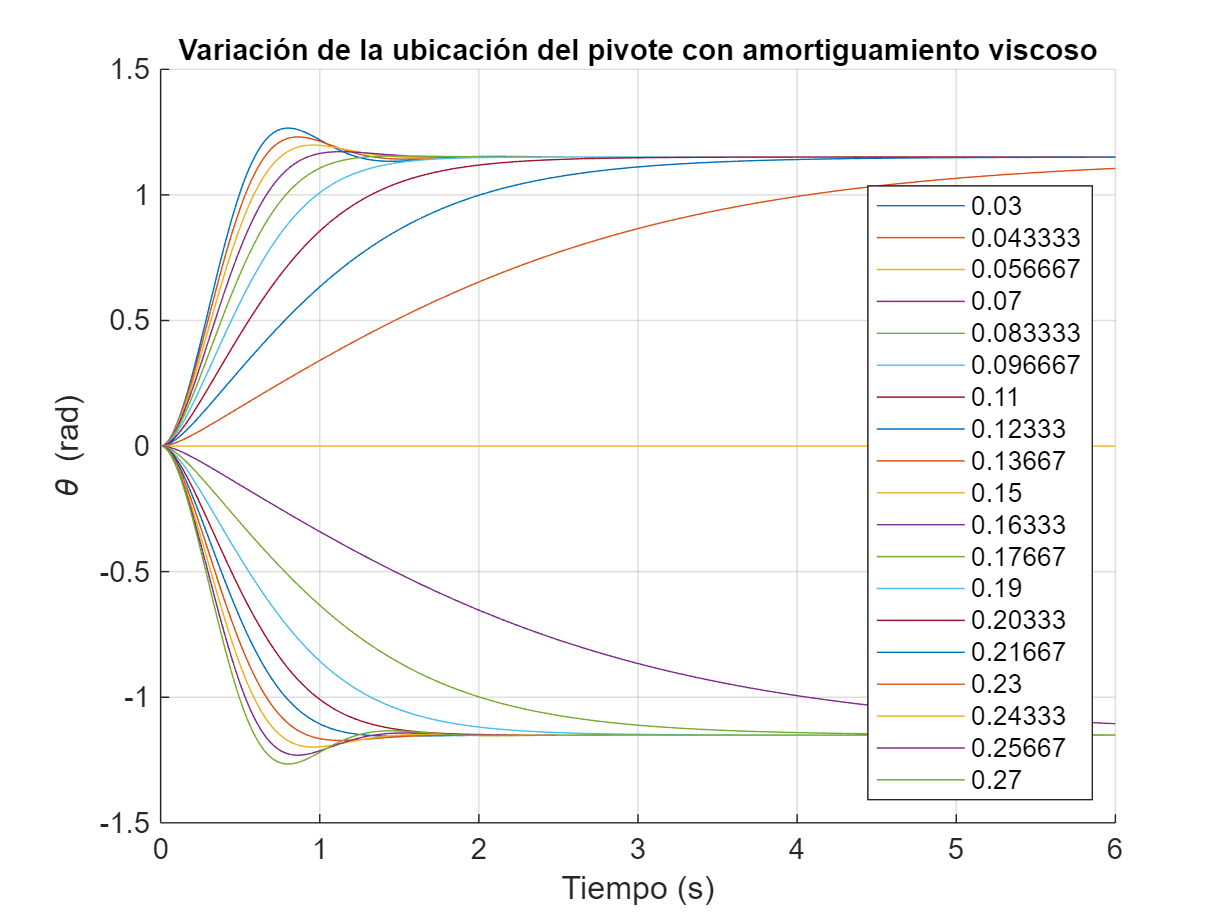

%% Intervalo de tiempo de simulación
tspan3 = linspace(0,6,500);
n = 19; % Número de simulaciones

%% Parámetros físicos del sistema
param3.mb = 0.1;      % Masa del cuerpo central (kg)
param3.m1 = 0.2;      % Masa del rotor 1 (kg)
param3.m2 = 0.2;      % Masa del rotor 2 (kg)
param3.g  = 9.81;     % Aceleración de la gravedad (m/s^2)
param3.c  = 0.1;      % Coeficiente de amortiguamiento viscoso (N·m·s/rad)

%% Condiciones iniciales
theta03 = 0.0;        % Ángulo inicial (rad)
theta_dot03 = 0;      % Velocidad angular inicial (rad/s)
x03 = [theta03; theta_dot03];

%% Valores de l1 que se desean analizar
l1_values = linspace(0.03,0.27,n)';

%% Inicialización de arreglos para almacenar resultados
theta_max = zeros(n,1);   % Ángulo máximo alcanzado
theta_min = zeros(n,1);   % Ángulo mínimo alcanzado
d         = zeros(n,1);   % Distancia pivote–centro de gravedad
theta_eq  = zeros(n,1);   % Ángulo de equilibrio

%% Figura para visualizar las trayectorias temporales
figure
hold on
grid on
xlabel('Tiempo (s)')
ylabel('\theta (rad)')
title('Variación de la ubicación del pivote con amortiguamiento viscoso', ...
      'FontSize',10,'FontWeight','bold')

for i = 1:n
    
    %% Actualizar parámetros geométricos
    param3.l1 = l1_values(i);          % Distancia al rotor 1
    param3.l2 = 0.30 - param3.l1;      % Distancia al rotor 2
    
    %% Recalcular parámetros derivados del modelo
    param3 = aeropendulum_compute_params(param3);

    %% Simulación del sistema dinámico
    [t3,theta3,theta_dot3] = simulate_aeropendulum(param3,x03,tspan3,@thrust_constant);

    %% Graficar respuesta temporal
    plot(t3,theta3)

    %% Guardar características de la señal
    theta_max(i) = max(theta3);     % Máximo
    theta_min(i) = min(theta3);     % Mínimo
    d(i)         = param3.d;        % Distancia pivote–centro de gravedad
    theta_eq(i)  = theta3(end);     % Ángulo de equilibrio

end

%% Mostrar leyenda con los valores de l1
legend(string(l1_values),'Location','southeast')


%% Tabla de resultados
results_table = table(l1_values, d, theta_max, theta_min, theta_eq, ...
    'VariableNames', {'l1_m','d_m','Theta_max_rad','Theta_min_rad','Theta_eq_rad'});

disp(results_table)

      l1_m         d_m        Theta_max_rad    Theta_min_rad    Theta_eq_rad
    ________    __________    _____________    _____________    ____________

        0.03         -0.12          1.266                 0          1.1508 
    0.043333      -0.10667         1.2308                 0          1.1508 
    0.056667     -0.093333         1.1985                 0          1.1508 
        0.07         -0.08         1.1719                 0          1.1508 
    0.083333     -0.066667          1.155                 0          1.1508 
    0.096667     -0.053333         1.1508                 0          1.1508 
        0.11         -0.04         1.1508                 0          1.1508 
     0.12333     -0.026667         1.1502                 0          1.1502 
     0.13667     -0.013333         1.1055                 0

Véase que todos estos sistemas un punto de equilibrio igual en su valor absoluto, excepto cuando el centro de gravedad está en el pivote donde no hay dinámica. 

#### **3.2.4 Puntos de Equilibrio**

Veamos que el modelo del balancín eólico predice este comportamiento.Se considera la energía mecánica total del sistema, definida como la suma de la energía cinética rotacional, la energía potencial gravitacional y la energía potencial asociada al torque impuesto. Esta energía está dada por


$$V(\theta,\dot{\theta})=
\frac{1}{2}J\dot{\theta}^2 + mgd\sin(\theta) - \tau \theta,$$


donde $\tau = T_1l_1 - T_2l_2$ representa el torque constante generado por los empujes aerodinámicos. Derivando esta expresión respecto al tiempo se obtiene


$$\dot V =
J\dot{\theta}\ddot{\theta} + mgd\cos(\theta)\dot{\theta} - \tau \dot{\theta}.$$


Utilizando la ecuación de movimiento del sistema y sustituyendo la aceleración angular en $\dot{V}$ se obtiene que la variación de la energía del sistema depende solo del término de fricción viscosa


$$\dot V =
\dot{\theta}(\tau - mgd\cos(\theta) - c\dot{\theta})
+
mgd\cos(\theta)\dot{\theta}
-
\tau\dot{\theta}.\\

\dot V =
\tau\dot{\theta}
-
mgd\cos(\theta)\dot{\theta}
-
c\dot{\theta}^2
+
mgd\cos(\theta)\dot{\theta}
-
\tau\dot{\theta}.\\

\dot V = -c\dot{\theta}^2.$$


Por lo tanto, para un coeficiente de amortiguación positivo, $\dot V \le 0,$ con igualdad únicamente cuando $\dot{\theta}=0$. Esto implica que la energía mecánica del sistema es monótonamente decreciente debido a la fricción viscosa y hay disipación de la energía. Dado que la energía mecánica es decreciente y está acotada inferiormente, se tiene que


$$\lim_{t\to\infty}\dot{\theta}(t)=0.$$


En este régimen estacionario también se cumple que $\dot{\theta} = 0\text{ rad/s}, \ddot{\theta}=0 \text{ rad/s}^2$. Sustituyendo estas condiciones de equilibrio en la dinámica del sistema se obtiene la condición de equilibrio


$$\tau - mgd\cos(\theta^*) = 0.$$


Los puntos de equilibrio corresponden a


$$\theta^* = \pm \arccos \left(\frac{T_1l_1 - T_2l_2}{mgd}\right).$$


Los puntos de equilibrio se denotarán como $(\mathbf{x_e}, \mathbf{u_e})$. Véase que el sistema tiene dos puntos de equilibrio. Los equilibrios estables corresponden a mínimos locales de la energía potencial efectiva, mientras que los máximos corresponden a equilibrios inestables. Debido a la disipación de energía introducida por la fricción viscosa, las trayectorias del sistema convergen hacia el mínimo de energía potencial, lo cual explica la convergencia observada en las simulaciones. Para el Caso 2 estudiado, con empuje $T_1 = T_2 = 1 \text{ N}$ igual y constante y con la definición previemente fijada de $d
$, vemos que los puntos predichos por el modelo matemático son, 


$$\theta^* = \pm \arccos \left(\frac{2}{mg}\right).\\$$


Véase que el punto de equilibrio no depende de $l_1$, como se ha comprobado en la simulación del Caso 3. Para los parámetros seleccionados $\theta^* \approx \pm 1.15 \text{ rad} $, que es exactamente lo que observamos en la simulación del Caso 3, negativo si $d
$ está en el brazo $l_1$, positivo si $d
$ está en el brazo $l_2$.

#### 3.2.5 Caso 4: Variación de la Masa

Con los mismos parámetros del Caso 3, con $l_1 = 0.21 \text{ m}, l_2 = 0.9 \text{ m}$ pero variando la masa entre $0.3 - 1.0 \text{ kg}$, comprobamos que los puntos de equilibrio cumplen $\theta^* = - \arccos 2/mg.$

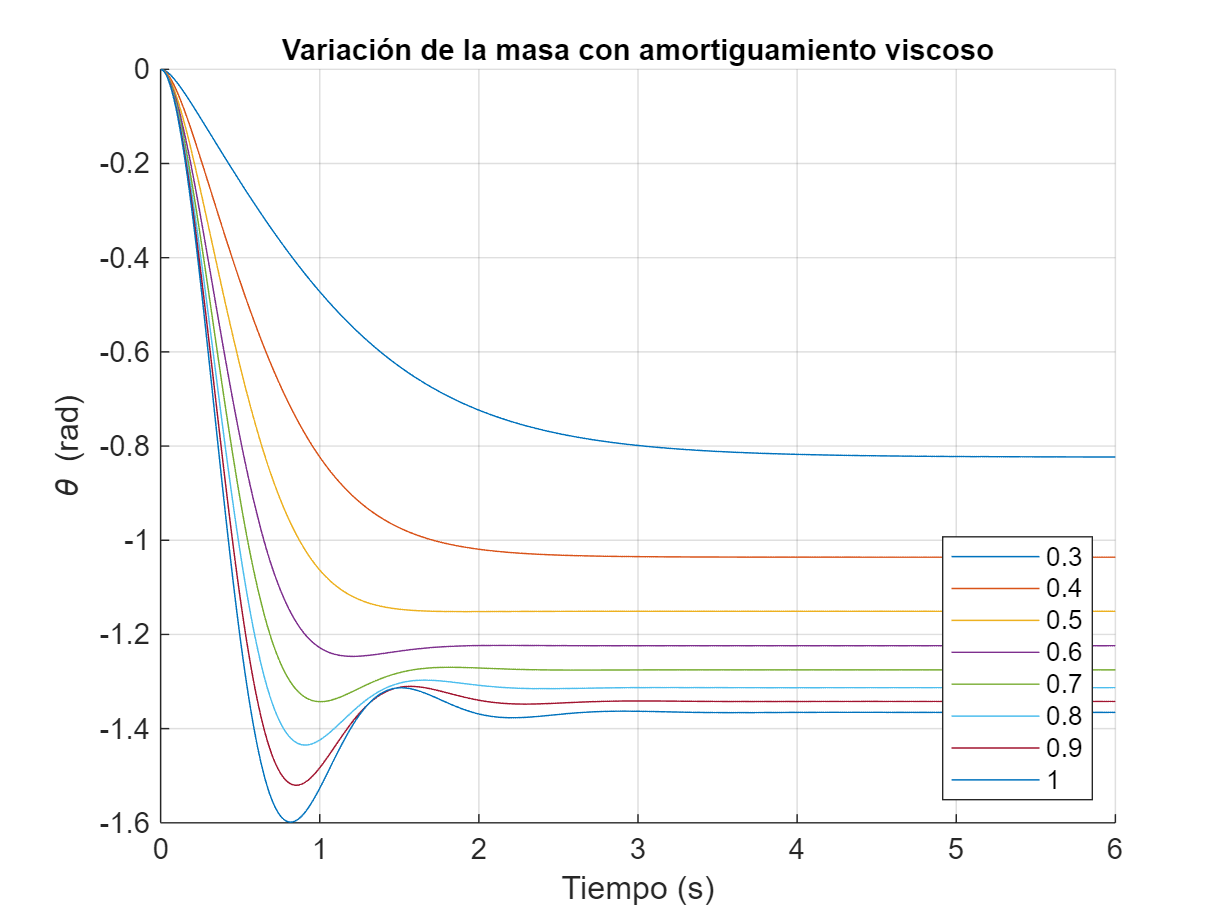

%% Intervalo de tiempo de simulación
tspan4 = linspace(0,6,500);
n = 8; % Número de simulaciones

%% Parámetros físicos del sistema
param4.g  = 9.81;     % Aceleración de la gravedad (m/s^2)
param4.c  = 0.1;      % Coeficiente de amortiguamiento viscoso (N·m·s/rad)
param4.l1 = 0.21;     % Distancia al rotor 1 (m)
param4.l2 = 0.09;     % Distancia al rotor 2 (m)

%% Condiciones iniciales
theta04 = 0.0;        % Ángulo inicial (rad)
theta_dot04 = 0;      % Velocidad angular inicial (rad/s)
x04 = [theta04; theta_dot04];

%% Valores de masa total que se desean analizar
m_values = linspace(0.3,1,n)';

%% Inicialización de arreglos para almacenar resultados
d        = zeros(n,1);   % Distancia pivote–centro de gravedad
theta_eq = zeros(n,1);   % Ángulo de equilibrio

%% Figura para visualizar las trayectorias temporales
figure
hold on
grid on
xlabel('Tiempo (s)')
ylabel('\theta (rad)')
title('Variación de la masa con amortiguamiento viscoso','FontSize',10,'FontWeight','bold')

for i = 1:n
    
    %% Actualizar masa total
    param4.m = m_values(i);

    % Distribución de masas
    param4.mb = 0.2*param4.m;   % Masa del cuerpo central
    param4.m1 = 0.4*param4.m;   % Masa rotor 1
    param4.m2 = 0.4*param4.m;   % Masa rotor 2

    %% Recalcular parámetros derivados
    param4 = aeropendulum_compute_params(param4);

    %% Simulación del sistema dinámico
    [t4,theta4,theta_dot4] = simulate_aeropendulum(param4,x04,tspan4,@thrust_constant);

    %% Graficar respuesta temporal
    plot(t4,theta4)

    %% Guardar resultados
    d(i)        = param4.d;       % Distancia pivote–centro de gravedad
    theta_eq(i) = theta4(end);    % Ángulo de equilibrio alcanzado

end

%% Mostrar leyenda con los valores de masa
legend(string(m_values),'Location','southeast')

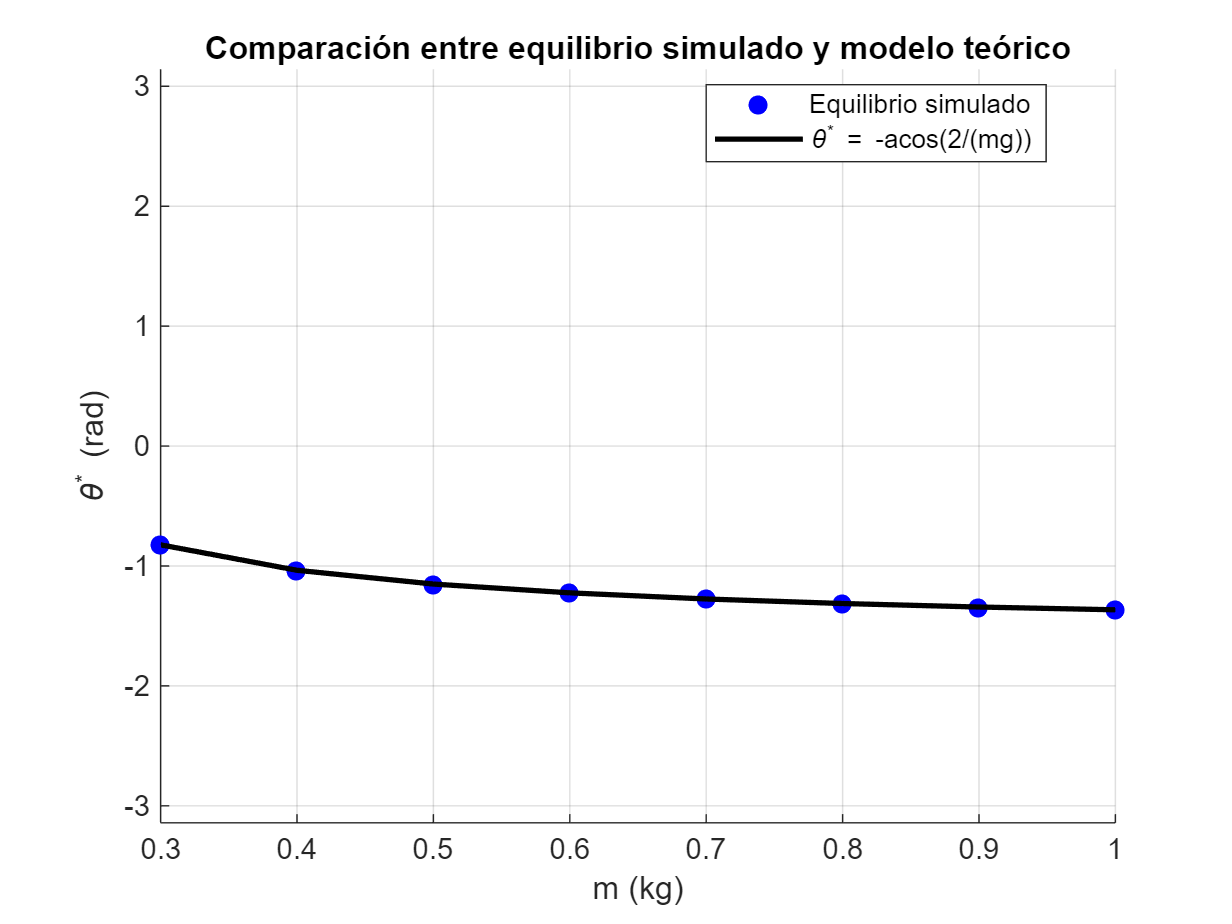


%% Comparación con el modelo teórico del equilibrio

figure
hold on
grid on

% Equilibrios obtenidos por simulación
plot(m_values,theta_eq,'bo','MarkerFaceColor','b')

% Modelo teórico
theta_theory = -acos(2./(m_values*param4.g));
plot(m_values,theta_theory,'k','LineWidth',1.8)

xlabel('m (kg)')
ylabel('\theta^* (rad)')
title('Comparación entre equilibrio simulado y modelo teórico')

legend('Equilibrio simulado','\theta^* = -acos(2/(mg))','Location','best')

ylim([-pi pi])

Véase que el modelo teórico predice los resultados de la simulación, lo que indica que está bien implementado.

#### **3.2.6 Caso 5: Variación del coeficiente de fricción**

Con un alto coeficiente de fricción se espera que el sistema se estabilize más rápido. Para los parámetros por defecto, con  $l_1 = 0.21 \text{ m}, l_2 = 0.9 \text{ m}$. y valores del coeficiente de fricción variando logaritmicamente entre $c = 0.001\text{ N\cdot m\cdot s/rad} -  1 \text{ N\cdot m\cdot s/rad}$, se realiza el estudio de parámetros.

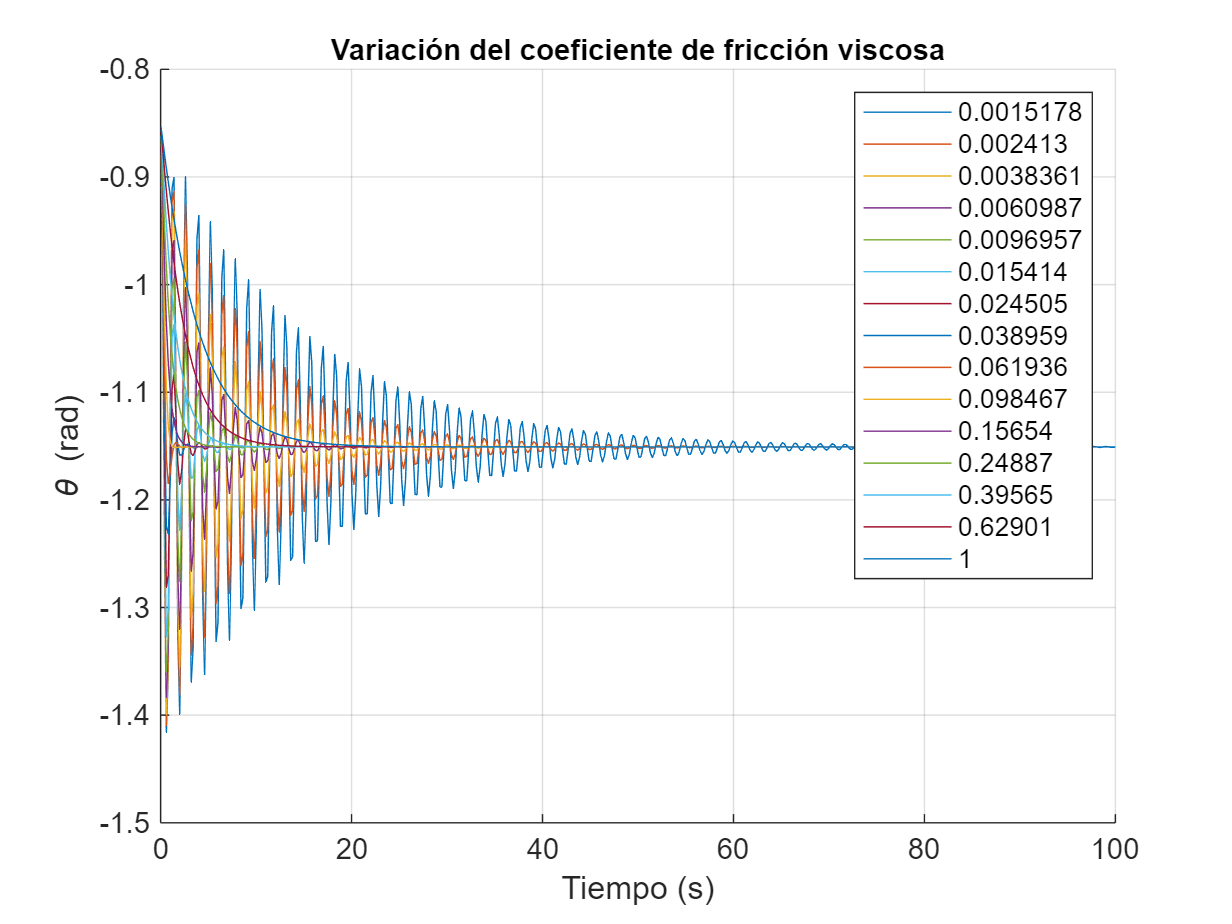

%% Intervalo de tiempo de simulación
tspan5 = linspace(0,100,500);
n = 150; % Número de simulaciones

%% Parámetros físicos del sistema
param5.g  = 9.81;     
param5.l1 = 0.21;     
param5.l2 = 0.09;     

%% Masa total fija
param5.m = 0.5;       

% Distribución de masas
param5.mb = 0.2*param5.m;   
param5.m1 = 0.4*param5.m;   
param5.m2 = 0.4*param5.m;   

%% Valores del coeficiente de fricción viscosa
c_values = logspace(-3,0,n)';   % mejor rango para detectar c_crit

%% Equilibrio teórico
theta_star = -acos(2/(param5.m*param5.g));

%% Condiciones iniciales
theta05 = theta_star + 0.3;        
theta_dot05 = 0;      
x05 = [theta05; theta_dot05];

%% Inicialización
theta_eq   = zeros(n,1);
t_settle   = NaN(n,1);

%% Figura de trayectorias
figure
hold on
grid on
xlabel('Tiempo (s)')
ylabel('\theta (rad)')
title('Variación del coeficiente de fricción viscosa','FontSize',10,'FontWeight','bold')

%% Tolerancia para tiempo de estabilización
tol = 0.02*abs(theta_star);

for i = 1:n
    
    %% Actualizar coeficiente de fricción
    param5.c = c_values(i);

    %% Recalcular parámetros derivados
    param5 = aeropendulum_compute_params(param5);

    %% Simulación
    [t5,theta5,theta_dot5] = simulate_aeropendulum(param5,x05,tspan5,@thrust_constant);

    %% Graficar algunas trayectorias
    if mod(i,10)==0
        plot(t5,theta5,'DisplayName',num2str(c_values(i)))
    end

    %% Guardar equilibrio numérico
    theta_eq(i) = theta5(end);

    %% Error respecto al equilibrio
    theta_error = theta5 - theta_star;
    abs_error = abs(theta_error);

    %% Tiempo de estabilización
    for k = 1:length(abs_error)

        if all(abs_error(k:end) < tol)
            t_settle(i) = t5(k);
            break
        end

    end

end

legend show


%% -----------------------------
%% Tiempo de estabilización vs fricción

figure
semilogx(c_values,t_settle,'o-','LineWidth',1.5)
grid on

xlabel('c (N·m·s/rad)')
ylabel('Tiempo de estabilización (s)')
title('Tiempo necesario para alcanzar el equilibrio')

%% -----------------------------
%% Cálculo del amortiguamiento crítico

[ts_min,idx] = min(t_settle);

c_crit_sim = c_values(idx);

disp(['Coeficiente de amortiguamiento crítico aproximado: ', num2str(c_crit_sim)])

Coeficiente de amortiguamiento crítico aproximado: 0.071179


disp(['Tiempo mínimo de estabilización: ', num2str(ts_min),' s'])

Tiempo mínimo de estabilización: 0.6012 s


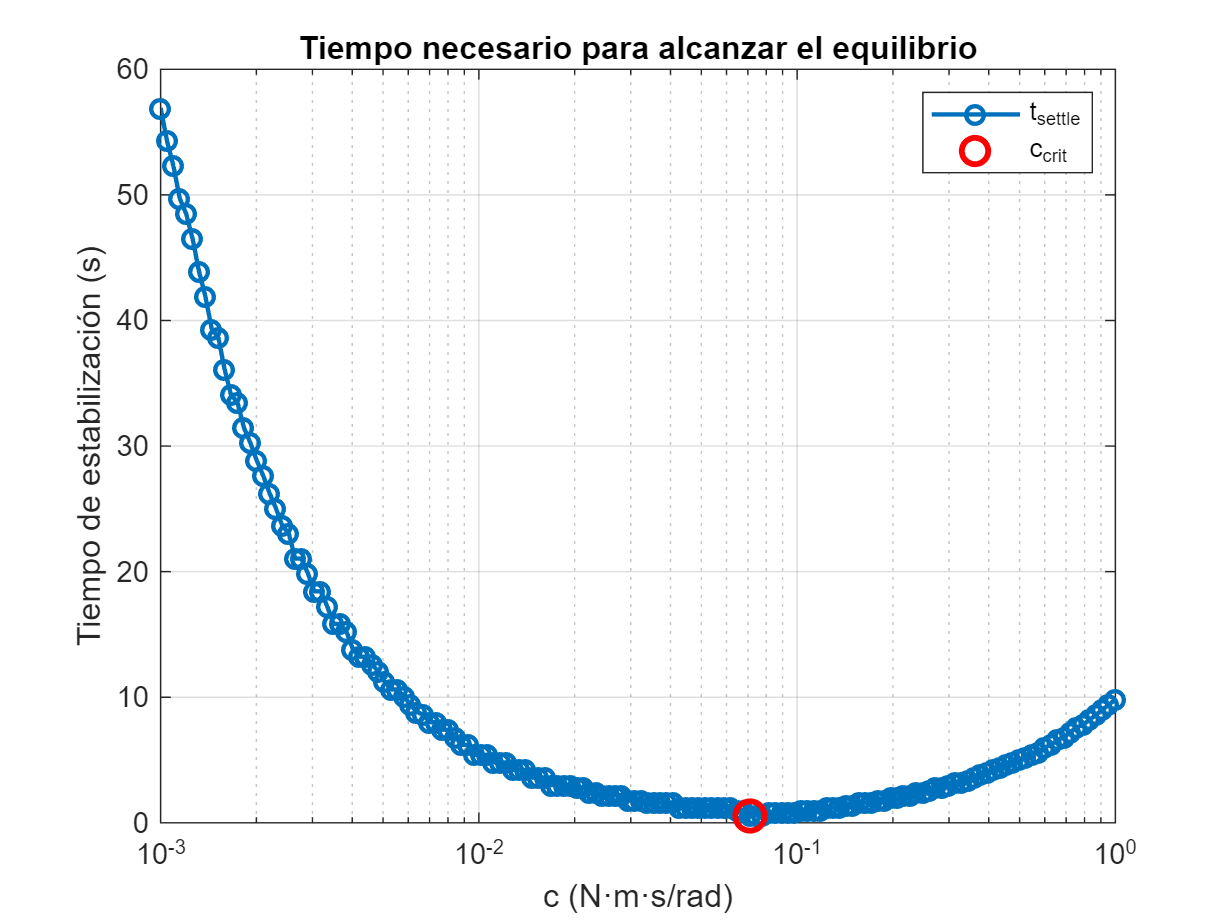


%% -----------------------------
%% Marcar punto crítico en la gráfica

hold on
plot(c_crit_sim,ts_min,'ro','MarkerSize',10,'LineWidth',2)
legend('t_{settle}','c_{crit}')

El resultado puede parecer contraintuitivo en un primer momento, pero conduce a una observación importante sobre la dinámica del sistema. El sistema puede clasificarse en tres regímenes de amortiguamiento: **subamortiguado, críticamente amortiguado y sobreamortiguado**. En el régimen subamortiguado, aumentar el coeficiente de fricción viscosa reduce las oscilaciones del sistema, lo que provoca que el tiempo necesario para alcanzar el equilibrio disminuya. Es decir, un mayor amortiguamiento ayuda a disipar más rápidamente la energía del sistema y, por tanto, acelera su estabilización. Cuando el coeficiente de amortiguamiento alcanza el valor de amortiguamiento crítico, el sistema llega al equilibrio en el menor tiempo posible sin presentar oscilaciones. Este punto corresponde al tiempo de estabilización mínimo, que en este caso se aproxima a $c_{crit} \approx 0.1 \text{ N\cdotp m}$.

Sin embargo, si el coeficiente de amortiguamiento continúa aumentando, el sistema pasa al régimen sobreamortiguado. En este caso, el movimiento del sistema se vuelve más lento porque la fricción es tan grande que limita la velocidad con la que el sistema puede desplazarse hacia el equilibrio. Como consecuencia, aunque ya no existen oscilaciones, el tiempo de estabilización vuelve a aumentar. Por lo tanto, existe un valor óptimo del coeficiente de amortiguamiento —el amortiguamiento crítico— que minimiza el tiempo necesario para que el sistema alcance el equilibrio correspondiente. 

#### **3.2.6 Linealización del modelo en el punto de equilibrio y coeficiente de amortiguamiento crítico teórico.**

Como este es un sistema no-lineal, y el coeficiente de amortiguamiento crítico solo está definido para sistemas lineales de segundo orden, se linealiza el modelo en el punto de equilibrio, y se halla el coeficiente de amortiguameinto crítico, para hacer la verificación del Caso 5. Teniendo el modelo dinámico del balancín eólico $\dot{x} = f(\mathbf{x},\mathbf{u})$, obtenemos para los parámetros particulares según la sección 3.2.4 el punto de equilibrio estable $(\mathbf{x_e}, \mathbf{u_e})$ tal que $f(\mathbf{x_e},\mathbf{u_e})=0.$

Se definen pequeñas perturbaciones alrededor del punto de equilibrio equilibrio


$$\mathbf{x(t)} = \mathbf{x_e} + \delta \mathbf{x(t)} \\
\mathbf{u(t)} = \mathbf{u_e} + \delta\mathbf{u(t)}$$


La función $f(\mathbf{x},\mathbf{u})$ se expande alrededor del punto de equilibrio usando una serie de Taylor de primer orden:


$$f(x,u) \approx f(x_e,u_e) + \left.\frac{\partial f}{\partial x}\right|_{x_e,u_e}\delta x + \left.\frac{\partial f}{\partial u}\right|_{x_e,u_e}\delta u$$


Como$f(\mathbf{x_e},\mathbf{u_e})=0.$, el sistema linealizado queda $\delta\dot{x} = A\,\delta x + B\,\delta u$ donde 


$$A =
\left.\frac{\partial f}{\partial x}\right|_{x_e,u_e},
\qquad
B =
\left.\frac{\partial f}{\partial u}\right|_{x_e,u_e}.$$


Las derivadas parciales son


$$\frac{\partial f}{\partial x} =
\left[
\begin{array}{cc}
0 & 1 \\
\frac{mgd}{J}\sin(x_1) & -\frac{c}{J}
\end{array}
\right], \qquad \frac{\partial f}{\partial u} =
\left[
\begin{array}{cc}
0 & 0 \\
\frac{l_1}{J} & \frac{l_2}{J}
\end{array}
\right]$$


Por lo tanto, el sistema linealizado alrededor de $(\mathbf{x_e}, \mathbf{u_e})$ es


$$\delta\dot{x} =
\left[
\begin{array}{cc}
0 & 1 \\
\frac{mgd}{J}\sin(x_{1e}) & -\frac{c}{J}
\end{array}
\right]
\delta x
+
\left[
\begin{array}{cc}
0 & 0 \\
\frac{l_1}{J} & \frac{l_2}{J}
\end{array}\right]
\delta u$$


A partir del modelo linealizado del sistema y considerando como salida el ángulo del péndulo $y = \theta = x_1,$ se tiene $C =
\begin{array}{cc}
[1 & 0]
\end{array}, \quad
D = 0.$ La función de transferencia de un sistema lineal en espacio de estados está dada por $G(s) = C(sI-A)^{-1}B + D$ [5].


$$sI-A =
\left[\begin{array}{cc}
s & -1 \\
-\frac{mgd}{J}\sin(\theta_e) & s + \frac{b}{J}
\end{array} \right].$$


El determinante de esta matriz es 


$$|sI-A| =s\left(s+\frac{c}{J}\right)
- \frac{mgd}{J}\sin(\theta_e) \\
|sI-A| = s^2 + \frac{c}{J}s - \frac{mgd}{J}\sin(\theta_e).$$


Por lo tanto, la función de transferencia entre las entradas $U_1(s)$, $U_2(s)$ y la salida $\Theta (s)$es


$$G(s) = \frac{l_1}{Js^2 + cs - mgd\sin(\theta_e)} U_1(s) + \frac{-l_2}{Js^2 + cs - mgd\sin(\theta_e)}U_2(s)$$


El denominador de la función de transferencia corresponde a un sistema de segundo orden. La forma estándar de un sistema de segundo orden es $s^2 + 2\zeta\omega_n s + \omega_n^2$, donde $\zeta$ es el coeficiente de amortiguamiento y $\omega_n$ la frecuencia natural. Comparando ambas expresiones se obtiene


$$2\zeta\omega_n = \frac{c}{J} \\
\omega_n^2 = \frac{mgd}{J}\sin(\theta_e).$$


De la segunda ecuación $\omega_n =
\sqrt{\frac{mgd}{J}\sin(\theta_e)}.$ El amortiguamiento crítico ocurre cuando $\zeta = 1$. Sustituyendo en la primera relación $\frac{c_{crit}}{J} = 2\omega_n,$ el coeficiente de amortiguamiento crítico del sistema es


$$c_{crit}=2\sqrt{-Jmgd\sin(\theta_e)}.$$


Para los parámetros del Caso 5, el amortiguamiento crítico rotacional,


$$c_{crit}=2\sqrt{-(0.0115\ \mathrm{kg\cdotp m^2})(0.5\ \mathrm{kg})(9.81\ \mathrm{m/s^2})(0.06\ \mathrm{m})\sin(-1.15)} = 0.111 \mathrm{N\cdotp m \cdotp s}$$


Véase que esto coincide aproximadamente con el amortiguamiento crítico hallado en el Caso 5. Discrepancias en coeficiente pueden deberse a la linealización del modelo.

#### **Simulación con empuje unilateral**

Retornamos a los parámetros originales, y cambiamos el empuje para que sea de un solo motor, en un valor alto. Se espera que sea capaz de sobreponerse al peso, y que el pendulo comienze a dar vueltas en sentido antihorario debido a la influencia del torque unilateral T1.

%% PRUEBA CON EMPUJE UNILATERAL
%% Parámetros físicos
params.m = 0.5;        % Masa (kg)
params.l1 = 0.4;       % Distancia al rotor 1 (m)
params.l2 = 0.2;       % Distancia al rotor 2 (m)
params.d = 0.2;        % Distancia al CG (m)
params.g = 9.81;       % Gravedad (m/s^2)
params.c = 0.1;        % Coeficiente de amortiguamiento (N·m·s/rad)
params.J = params.m*(params.l1^2 + params.l2^2)/3; % Momento de inercia


%% Condiciones iniciales
theta0 = 0;            % Posición en rad
theta_dot0 = 0;        % Velocidad angular en rad/s
x0 = [theta0; theta_dot0];

%% Para el control tomamos un solo motor con 10N
%% ---- Control de empuje ----
function [T1,T2] = unilateral_thrust_control(t, theta, theta_dot)
    T1 = 10;
    T2 = 0;
end

Como se esperaba, debido a la fuerza exclusivamente en un extremo, el pendulo comeinza a girar rápidamente en la dirección del torque T1, corroborando asi la intuición fisica. 

#### Simulación con cambio de entradas (uno no y otro si, y los dos si)

%% Parámetros físicos
params.m = 0.5;
params.l1 = 0.4;
params.l2 = 0.2;
params.d = 0.2;
params.g = 9.81;
params.c = 0.1;
params.J = params.m*(params.l1^2 + params.l2^2)/3;
tspan = linspace(0,10,500);
x0 = [0; 0];

**Entrada en escalón**

function [T1,T2] = thrust_step(t, theta, theta_dot)
    T1 = 2;
    T2 = 2;
end

simulate_aeropendulum(@aeropendulum_dynamics, @thrust_step, params, tspan, x0)

**Entrada Sinusoidal**

function [T1,T2] = thrust_sin(t, theta, theta_dot)
    T1 = 2*sin(2*pi*0.5*t) + 2;
    T2 = 2*sin(2*pi*0.5*t) + 2;
end

simulate_aeropendulum(@aeropendulum_dynamics, @thrust_sin, params, tspan, x0)

**Entrada Impulso**

function [T1, T2] = thrust_dirac(t, theta, theta_dot)
    syms t_sym
    t_sym = sym(t);          % force t to be symbolic, even if passed as double
    T1 = 10 * dirac(t_sym - 1);
    T2 = 10 * dirac(t_sym - 1);
end
simulate_aeropendulum(@aeropendulum_dynamics, @thrust_dirac, params, tspan, x0)

#### Simulación con el cambio de dos parámetros

### Discusión

#### Interpretación de los resultados

### Bibliografía

[1] R. Breganon, U. N. L. T. Alves, J. P. L. S. De Almeida, F. S. F. Ribeiro, M. Mendonça, R. H. C. Palácios, and M. A. F. Montezuma, “Model identification and H∞ control of an aeropendulum,” *Journal of Applied Research and Technology*, vol. 21, no. 4, pp. 526–534, 2023. doi: 10.22201/icat.24486736e.2023.21.4.1741.

[2] K. Charoensuk, T. Saneewong Na Ayuthaya, P. Poungsri, L. Kirasamutranon, V. Suthiphasilp, G. Prayutte, and K. Pawananont, “The modelling and control for design aero-pendulum via proportional–integral–derivative and integral-proportional derivative,” in *Proc. 13th International Electrical Engineering Congress (iEECON)*, 2025, pp. 1–6.

[3] J. A. Alvarado Cortes, A. D. Cortes Hernandez, O. A. Domínguez Ramírez, J. D. Ramírez Zamora, J. Ortega Ventura, and L. A. Martínez Rivera, “Diseño, construcción y validación experimental de un aeropéndulo de una hélice con un grado de libertad,” *Iberociencias*, vol. 4, no. 4, pp. 1063–1092, 2025, doi: 10.63371/ic.v4.n4.a424.

[4] H. Goldstein, C. Poole, and J. Safko, *Classical Mechanics*, 3rd ed. Boston, MA, USA: Addison-Wesley, 2002.

[5] C. M. Vélez S., *Sistemas dinámicos en contexto: Modelación matemática, simulación, estimación y control con MATLAB*, vol. 24. Editorial EAFIT, 2024.